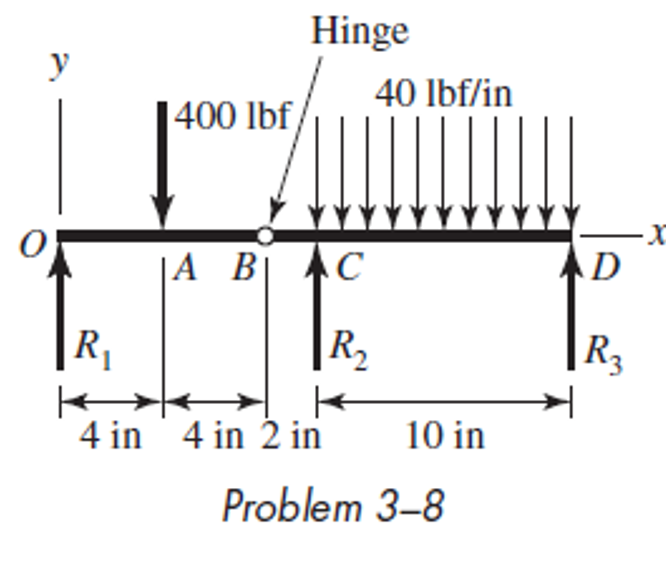

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'R1', 0);
b = b.add('concentrated', 'force', -400*u.lbf, 4*u.in);
b = b.add('hinge', 'force', 'Hb', 8*u.in);
b = b.add('reaction', 'force', 'R2', 10*u.in);
b = b.add('reaction', 'force', 'R3', 20*u.in);
b = b.add('distributed', 'force', -40*u.lbf/u.in, [10 20]*u.in);
b.L = 20*u.in;

# elastic curve

[y dy m v w rs ra hs ha] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{50\,x\,\left(95\,{\mathrm{in}}^{2}-2\,x^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\leq 4\,\mathrm{in}\\ -\frac{50\,\left(2\,x^{3}-48\,x^{2}\,\mathrm{in}+287\,x\,{\mathrm{in}}^{2}-256\,{\mathrm{in}}^{3}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\in \left(4\,\mathrm{in},8\,\mathrm{in}\right]\\ -\frac{100\,\left(x-10\,\mathrm{in}\right)\,\left(x^{2}-14\,x\,\mathrm{in}+50\,{\mathrm{in}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\in \left(8\,\mathrm{in},10\,\mathrm{in}\right]\\ -\frac{5\,\left(x-10\,\mathrm{in}\right)\,\left(x-20\,\mathrm{in}\right)\,\left(x^{2}-34\,x\,\mathrm{in}+220\,{\mathrm{in}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }10\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{50\,\left(95\,{\mathrm{in}}^{2}-6\,x^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\leq 4\,\mathrm{in}\\ -\frac{50\,\left(6\,x^{2}-96\,x\,\mathrm{in}+287\,{\mathrm{in}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\in \left(4\,\mathrm{in},8\,\mathrm{in}\right]\\ -\frac{100\,\left(3\,x^{2}-48\,x\,\mathrm{in}+190\,{\mathrm{in}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{lbf} & \text{ if }x\in \left(8\,\mathrm{in},10\,\mathrm{in}\right]\\ -\frac{20\,\left(x^{3}-48\,x^{2}\,\mathrm{in}+720\,x\,{\mathrm{in}}^{2}-3350\,{\mathrm{in}}^{3}\right)}{3\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }10\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 200\,x\,\mathrm{lbf} & \text{ if }x\leq 4\,\mathrm{in}\\ -200\,\left(x-8\,\mathrm{in}\right)\,\mathrm{lbf} & \text{ if }x\in \left(4\,\mathrm{in},10\,\mathrm{in}\right]\\ -20\,\left(x-12\,\mathrm{in}\right)\,\left(x-20\,\mathrm{in}\right)\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }10\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 200\,\mathrm{lbf} & \text{ if }x\leq 4\,\mathrm{in}\\ -200\,\mathrm{lbf} & \text{ if }x\in \left(4\,\mathrm{in},10\,\mathrm{in}\right]\\ -40\,\left(x-16\,\mathrm{in}\right)\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }10\,\mathrm{in}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<10\,\mathrm{in}\\ -40\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }10\,\mathrm{in}\leq x \end{array}\right.$$

ra

$$ra = \left(\begin{array}{cc} R_{1} & 200\,\mathrm{lbf}\\ R_{2} & 440\,\mathrm{lbf}\\ R_{3} & 160\,\mathrm{lbf} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & 200\,\mathrm{lbf} \end{array}\right)$$

# shear and moment diagram

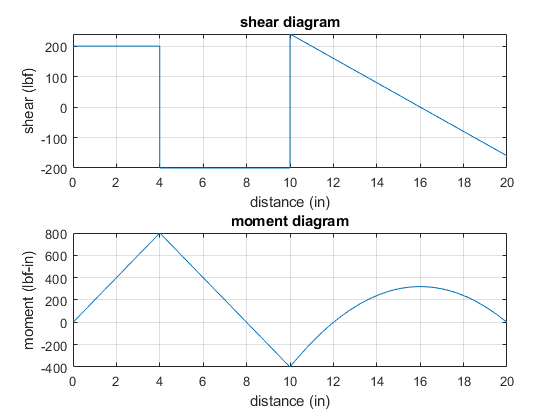

beam.shear_moment(m, v, [0 b.L], {'lbf' 'in'});

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear old_assum;